# Laboratorium 6

## **Próbkowanie i rekonstrukcja sygnałów **

### Janusz Pawlicki

## 1. Zadania

## 1.1

#### Przeprowadź rekonstrukcję sygnału ciągłego sin(ωkt) próbkowanego z częstotliwością 200Hz - szkic skryptu przedstawiono na rysunku 

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 4/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

## 1.2

#### Oznacz na wykresie czasowym węzły próbkowania wyznaczone przez okres próbkującej funkcji grzebieniowej δTp (t), gdzie Tp = 1/fp.

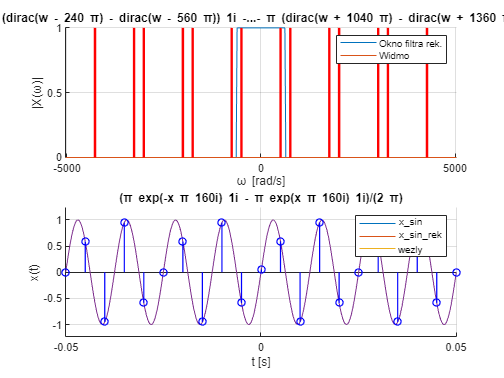

wezly = BND_t(1) : 1/fp : BND_t(2);
n = find(wezly == 0);
wezly(n) = 0.0001;
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t);
ezplot(x_sin_rek, BND_t);
stem(wezly, wezly_val, 'bo', 'LineWidth', 1);
xlabel('t [s]'); ylabel('x(t)');
legend('x\_sin', 'x\_sin\_rek', 'wezly');

## 1.3

#### Wykonaj rekonstrukcję sygnału sinusoidalnego o następujących częstotliwościach:

## a)

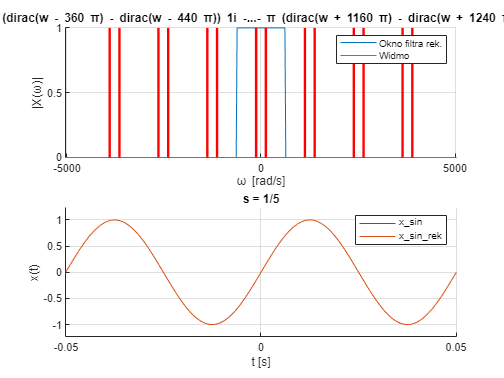

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 1/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 1/5');

## b)

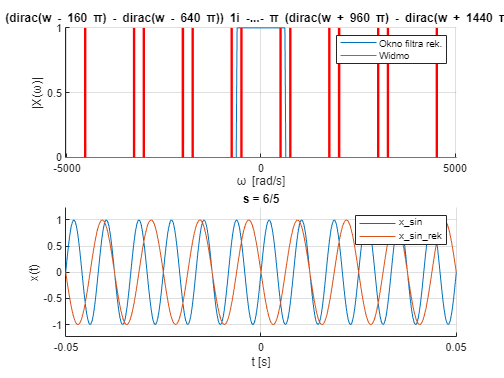

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 6/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 6/5');

## c)

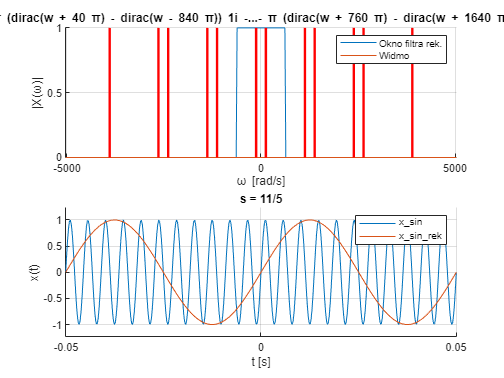

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 11/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 11/5');

## d)

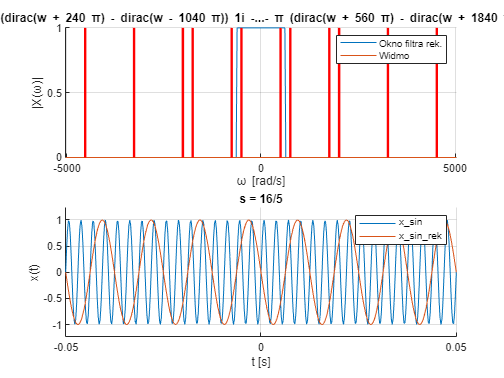

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 16/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 16/5');

## e)

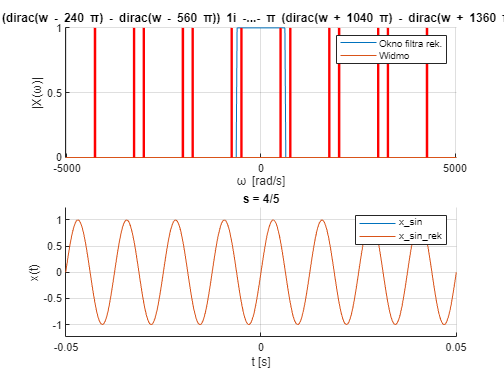

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 4/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 4/5');

## f)

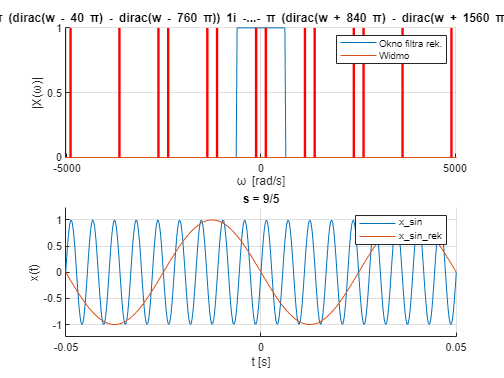

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 9/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 9/5');

## g)

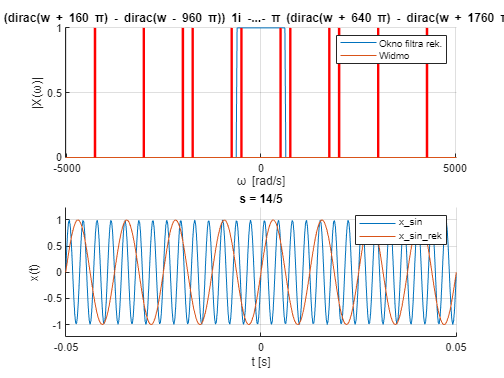

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 14/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 14/5');

## 1.4

#### Zastąp widmo sygnału sinusiodalnego `X_FT_sin` symetrycznym widmem o kształcie trójkątnym XΛ(jω) którego częstotliwość graniczna jest równa fg, wartość minimalna wynosi 0.0 a maksymlana 1.0. Pomijamy wówczas obliczenia transformaty za pomocą funkcji `fourier()` ale musimy pamiętać o dodaniu aliasów po prawej i lewej stronie. Przeprowadź analizę jak w Zad. 3

## a)

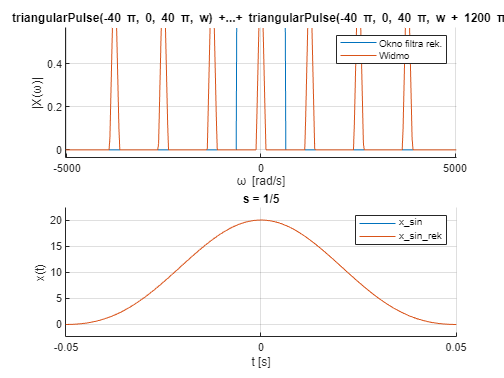

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 1/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 1/5');

## b)

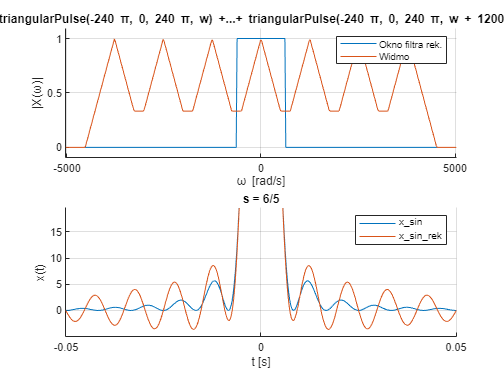

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 6/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 6/5');

## c)

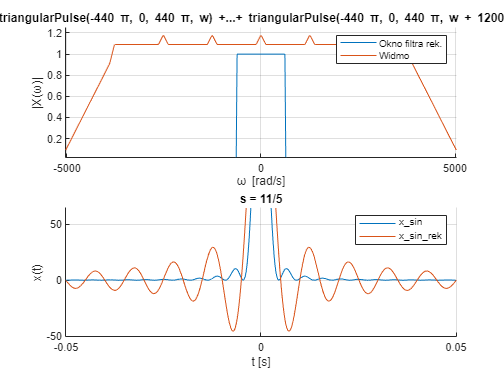

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 11/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 11/5');

## d)

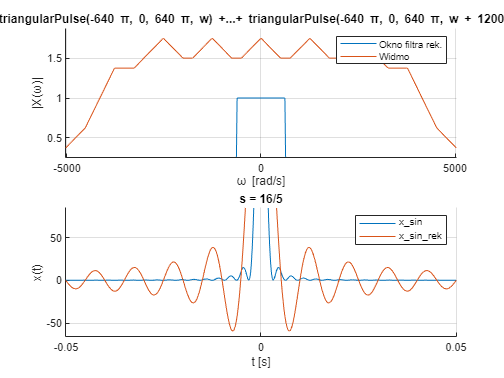

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 16/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 16/5');

## e)

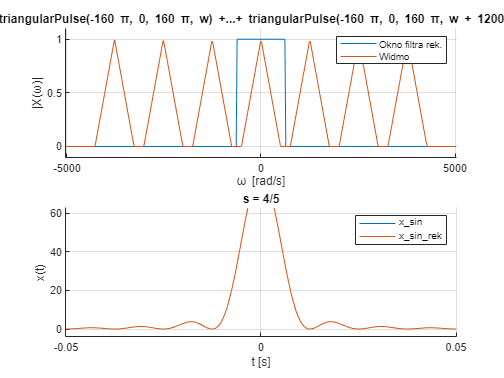

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 4/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 4/5');

## f)

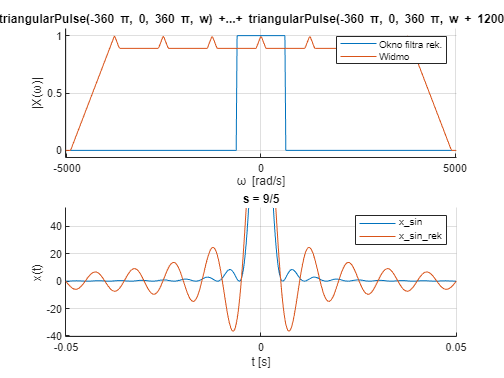

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 9/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 9/5');

## g)

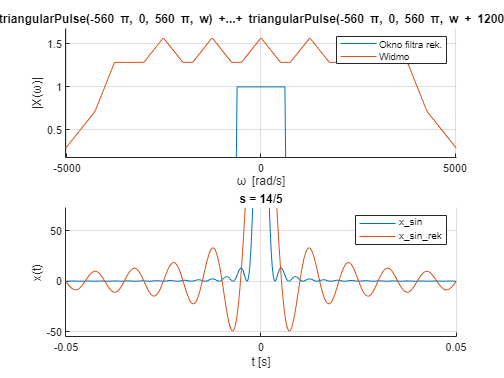

clear all;
close all;

syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;
s = 14/5; 
ws = s*wg;

x_tr = ifourier(triangularPulse(-ws,ws,w));
X_FT_tr_org = triangularPulse(-ws,ws,w);
X_FT_tr = X_FT_tr_org + ... % oryginal widma
    symsum((subs(X_FT_tr_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_tr_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

x_tr_rek = ifourier(X_FT_tr*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];

BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_tr,BND_w)

v_num = abs(double(subs(X_FT_tr, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_tr, BND_t); % syg. próbkowany
ezplot(x_tr_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
title('s = 14/5');

## 1.5

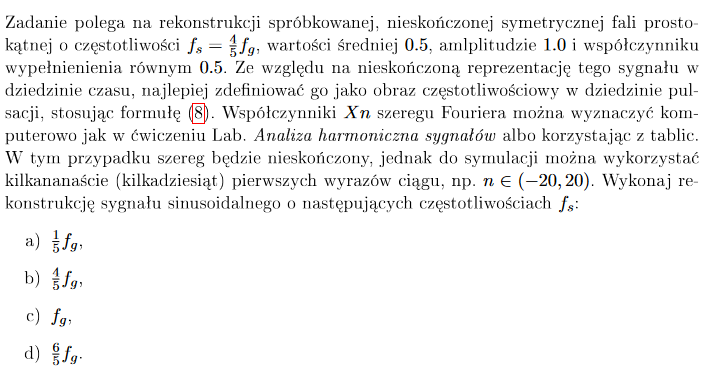

## a)

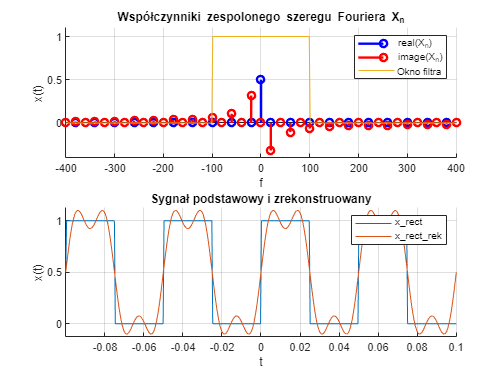

clear; close all;
syms t x w;

fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp;
wg = 2*pi*fg;
s = 1/5;
ws = wg*s;

fs = ws/2/pi;
Ts = 1/fs;

BND = [0;Ts];
x = rectangularPulse(fs*t);

NT = 20;
X = [];
ind = -NT : NT;
for n = ind
    Xn = (1/Ts)*int(x*exp(-1i*ws*n*t), t, BND);
    X(n + NT + 1) = Xn;
end

figure; 
subplot(2,1,1);
hold on;
stem(ind*fs, real(X), 'b', 'LineWidth', 2);
xlabel('f [Hz]')
stem(ind*fs, imag(X), 'r', 'LineWidth', 2);

BND_w = [-2*fp;2*fp];
FILT_FT = rectangularPulse(-fg,fg,w);
XX = [];
for n = ind
    if(abs(n*fs)<=fg)
        XX(n+NT+1) = X(n+NT+1);
    else
        XX(n+NT+1) = 0;
    end
end
ezplot(FILT_FT, BND_w);
axis([-400 400 -0.4 1.1])

grid on;
legend('real(X_n)','image(X_n)','Okno filtra','Location','NorthEast')
xlabel('f'); ylabel('x(t)');
title('Współczynniki zespolonego szeregu Fouriera X_n')

subplot(2,1,2);
hold on;
x2 = rectangularPulse(-4*Ts/2,-3*Ts/2, t) + rectangularPulse(-2*Ts/2,-Ts/2, t) + rectangularPulse(0,Ts/2, t) + rectangularPulse(2*Ts/2,3*Ts/2, t);
ezplot(x2, [-2*Ts 2*Ts])

step = (BND(2) - BND(1))/1000;
tt = [BND(1)-2*Ts : step : BND(2) + Ts];
xx2 = zeros(1,length(tt));
for n = -NT : NT
xx_n = XX(NT+n+1)*exp(j*ws*n*tt);
xx2 = xx2 + xx_n;
end
plot(tt,real(xx2));
grid on;
xlabel('t'); ylabel('x(t)');
legend('x\_rect','x\_rect\_rek');
title('Sygnał podstawowy i zrekonstruowany')

## b)

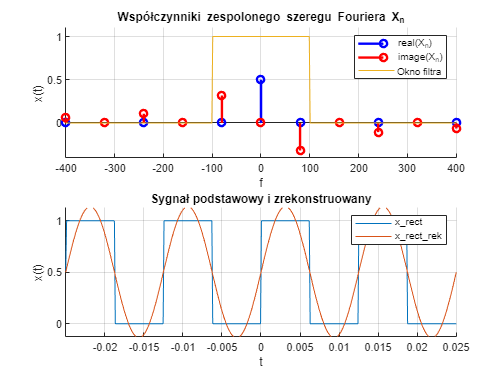

clear; close all;
syms t x w;

fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp;
wg = 2*pi*fg;
s = 4/5;
ws = wg*s;

fs = ws/2/pi;
Ts = 1/fs;

BND = [0;Ts];
x = rectangularPulse(fs*t);

NT = 20;
X = [];
ind = -NT : NT;
for n = ind
    Xn = (1/Ts)*int(x*exp(-1i*ws*n*t), t, BND);
    X(n + NT + 1) = Xn;
end

figure; 
subplot(2,1,1);
hold on;
stem(ind*fs, real(X), 'b', 'LineWidth', 2);
xlabel('f [Hz]')
stem(ind*fs, imag(X), 'r', 'LineWidth', 2);

BND_w = [-2*fp;2*fp];
FILT_FT = rectangularPulse(-fg,fg,w);
XX = [];
for n = ind
    if(abs(n*fs)<=fg)
        XX(n+NT+1) = X(n+NT+1);
    else
        XX(n+NT+1) = 0;
    end
end
ezplot(FILT_FT, BND_w);
axis([-400 400 -0.4 1.1])

grid on;
legend('real(X_n)','image(X_n)','Okno filtra','Location','NorthEast')
xlabel('f'); ylabel('x(t)');
title('Współczynniki zespolonego szeregu Fouriera X_n')

subplot(2,1,2);
hold on;
x2 = rectangularPulse(-4*Ts/2,-3*Ts/2, t) + rectangularPulse(-2*Ts/2,-Ts/2, t) + rectangularPulse(0,Ts/2, t) + rectangularPulse(2*Ts/2,3*Ts/2, t);
ezplot(x2, [-2*Ts 2*Ts])

step = (BND(2) - BND(1))/1000;
tt = [BND(1)-2*Ts : step : BND(2) + Ts];
xx2 = zeros(1,length(tt));
for n = -NT : NT
xx_n = XX(NT+n+1)*exp(j*ws*n*tt);
xx2 = xx2 + xx_n;
end
plot(tt,real(xx2));
grid on;
xlabel('t'); ylabel('x(t)');
legend('x\_rect','x\_rect\_rek');
title('Sygnał podstawowy i zrekonstruowany')

## c)

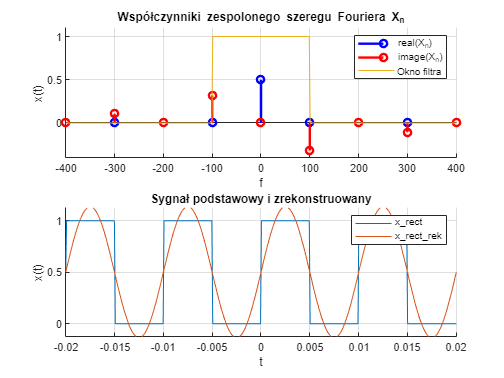

clear; close all;
syms t x w;

fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp;
wg = 2*pi*fg;
s = 5/5;
ws = wg*s;

fs = ws/2/pi;
Ts = 1/fs;

BND = [0;Ts];
x = rectangularPulse(fs*t);

NT = 20;
X = [];
ind = -NT : NT;
for n = ind
    Xn = (1/Ts)*int(x*exp(-1i*ws*n*t), t, BND);
    X(n + NT + 1) = Xn;
end

figure; 
subplot(2,1,1);
hold on;
stem(ind*fs, real(X), 'b', 'LineWidth', 2);
xlabel('f [Hz]')
stem(ind*fs, imag(X), 'r', 'LineWidth', 2);

BND_w = [-2*fp;2*fp];
FILT_FT = rectangularPulse(-fg,fg,w);
XX = [];
for n = ind
    if(abs(n*fs)<=fg)
        XX(n+NT+1) = X(n+NT+1);
    else
        XX(n+NT+1) = 0;
    end
end
ezplot(FILT_FT, BND_w);
axis([-400 400 -0.4 1.1])

grid on;
legend('real(X_n)','image(X_n)','Okno filtra','Location','NorthEast')
xlabel('f'); ylabel('x(t)');
title('Współczynniki zespolonego szeregu Fouriera X_n')

subplot(2,1,2);
hold on;
x2 = rectangularPulse(-4*Ts/2,-3*Ts/2, t) + rectangularPulse(-2*Ts/2,-Ts/2, t) + rectangularPulse(0,Ts/2, t) + rectangularPulse(2*Ts/2,3*Ts/2, t);
ezplot(x2, [-2*Ts 2*Ts])

step = (BND(2) - BND(1))/1000;
tt = [BND(1)-2*Ts : step : BND(2) + Ts];
xx2 = zeros(1,length(tt));
for n = -NT : NT
xx_n = XX(NT+n+1)*exp(j*ws*n*tt);
xx2 = xx2 + xx_n;
end
plot(tt,real(xx2));
grid on;
xlabel('t'); ylabel('x(t)');
legend('x\_rect','x\_rect\_rek');
title('Sygnał podstawowy i zrekonstruowany')

## d)

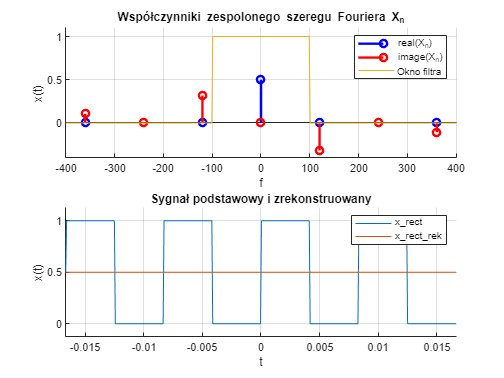

clear; close all;
syms t x w;

fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp;
wg = 2*pi*fg;
s = 6/5;
ws = wg*s;

fs = ws/2/pi;
Ts = 1/fs;

BND = [0;Ts];
x = rectangularPulse(fs*t);

NT = 20;
X = [];
ind = -NT : NT;
for n = ind
    Xn = (1/Ts)*int(x*exp(-1i*ws*n*t), t, BND);
    X(n + NT + 1) = Xn;
end

figure; 
subplot(2,1,1);
hold on;
stem(ind*fs, real(X), 'b', 'LineWidth', 2);
xlabel('f [Hz]')
stem(ind*fs, imag(X), 'r', 'LineWidth', 2);

BND_w = [-2*fp;2*fp];
FILT_FT = rectangularPulse(-fg,fg,w);
XX = [];
for n = ind
    if(abs(n*fs)<=fg)
        XX(n+NT+1) = X(n+NT+1);
    else
        XX(n+NT+1) = 0;
    end
end
ezplot(FILT_FT, BND_w);
axis([-400 400 -0.4 1.1])

grid on;
legend('real(X_n)','image(X_n)','Okno filtra','Location','NorthEast')
xlabel('f'); ylabel('x(t)');
title('Współczynniki zespolonego szeregu Fouriera X_n')

subplot(2,1,2);
hold on;
x2 = rectangularPulse(-4*Ts/2,-3*Ts/2, t) + rectangularPulse(-2*Ts/2,-Ts/2, t) + rectangularPulse(0,Ts/2, t) + rectangularPulse(2*Ts/2,3*Ts/2, t);
ezplot(x2, [-2*Ts 2*Ts])

step = (BND(2) - BND(1))/1000;
tt = [BND(1)-2*Ts : step : BND(2) + Ts];
xx2 = zeros(1,length(tt));
for n = -NT : NT
xx_n = XX(NT+n+1)*exp(j*ws*n*tt);
xx2 = xx2 + xx_n;
end
plot(tt,real(xx2));
grid on;
xlabel('t'); ylabel('x(t)');
legend('x\_rect','x\_rect\_rek');
title('Sygnał podstawowy i zrekonstruowany')